clear;
mklist = 'o+*sd<p';
alglist = {'Origin', 'MatchSync', 'MatchLift', 'MatchALS', 'JOMGM', 'CDMGM', 'FMGM'};
cmap = lines(7);
cmap(end, :) = 0;

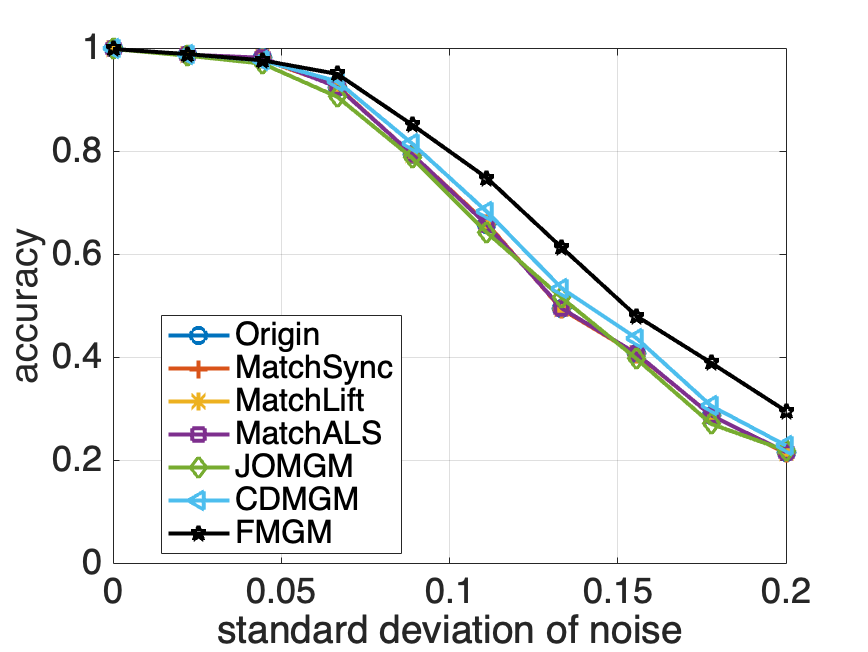

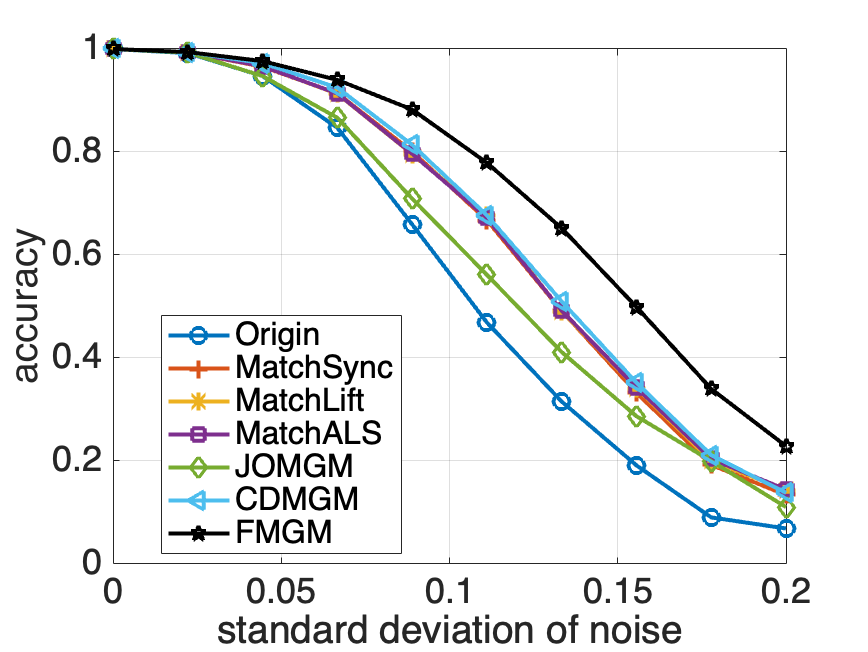

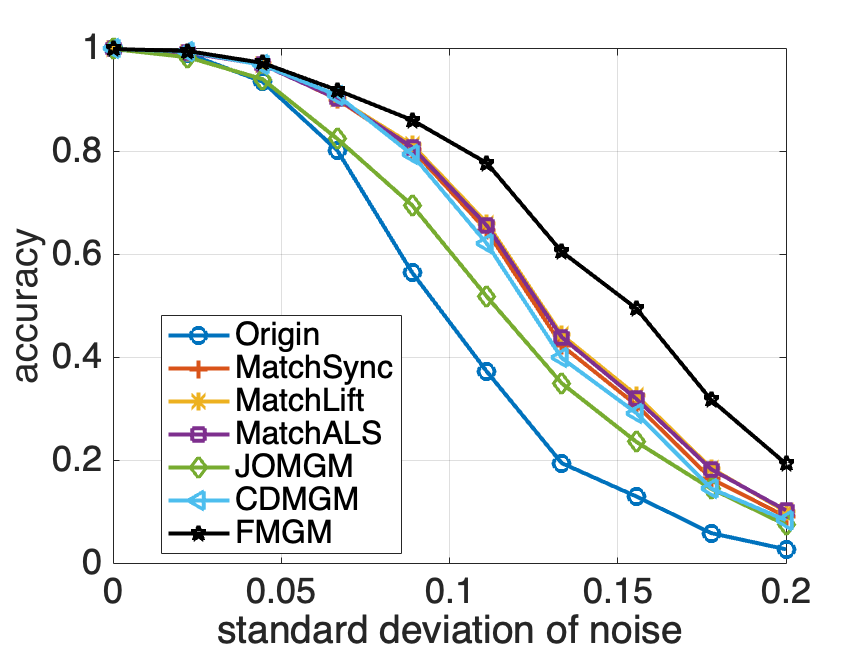

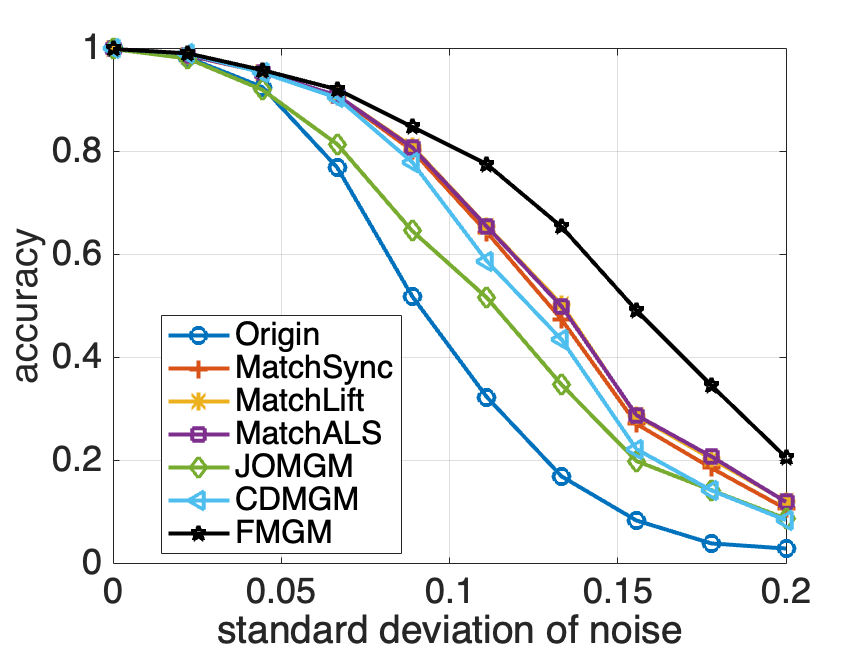

num = 10;
noise = linspace(0, 0.2, num);
for i = [3, 6, 9, 12]
    fname = ['acc_noise_',  num2str(i), '.mat'];
    acc = importdata(fname);
    figure, hold on; 
    for k = 1:length(alglist)
        plot(noise, acc(:, k), ['-', mklist(k)], 'DisplayName', alglist{k}, 'Color', cmap(k, :));
    end
    hold off;
    ylim([0, 1]);
    legend('Location', 'best');
    xlabel('standard deviation of noise');
    ylabel('accuracy');
    exportgraphics(gcf, ['./imgs/', 'acc_', num2str(i), '_noise.pdf']);
end

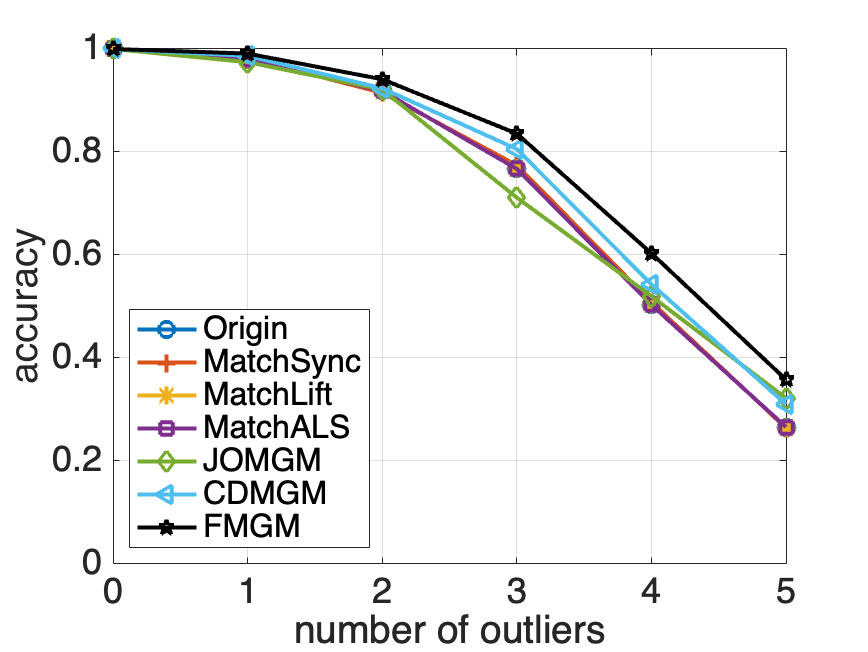

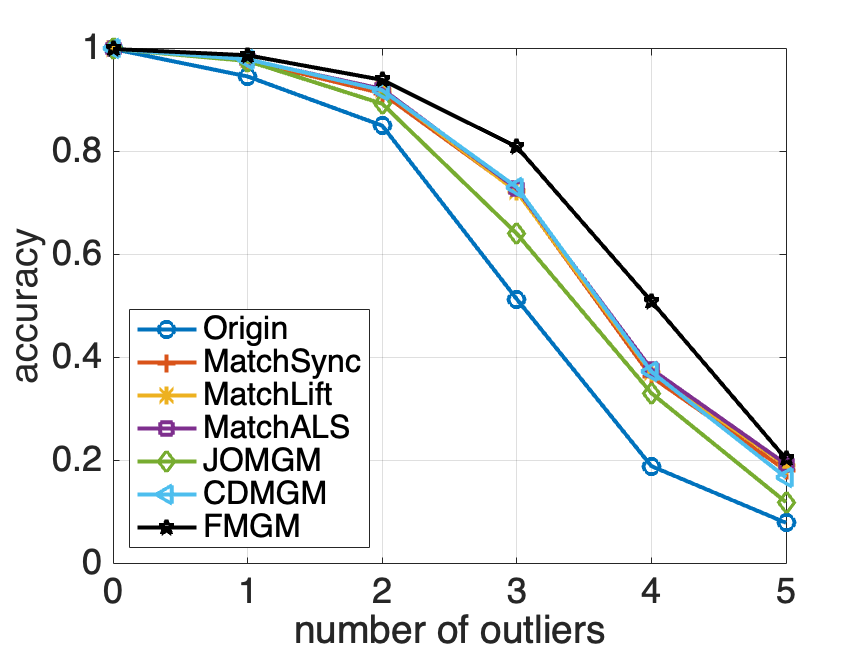

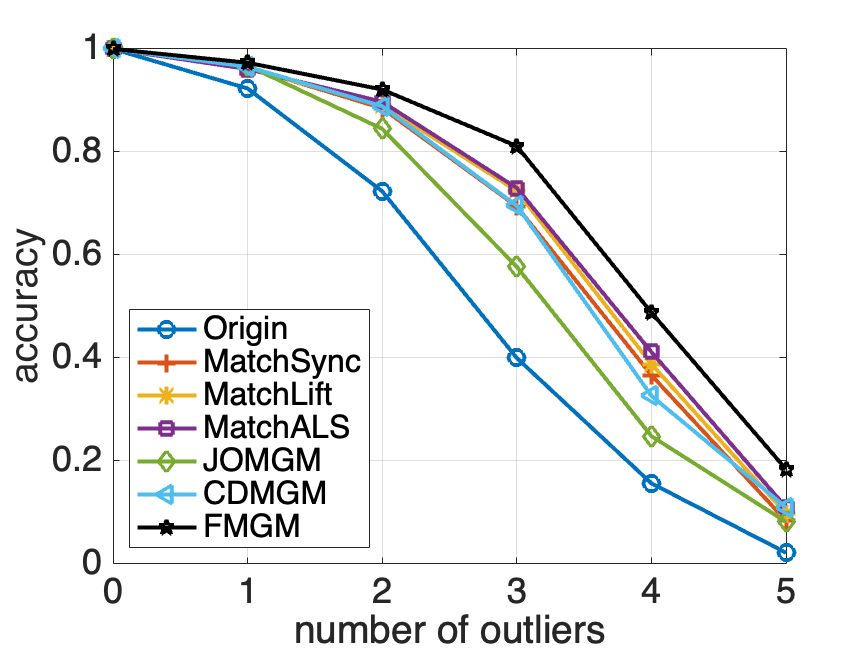

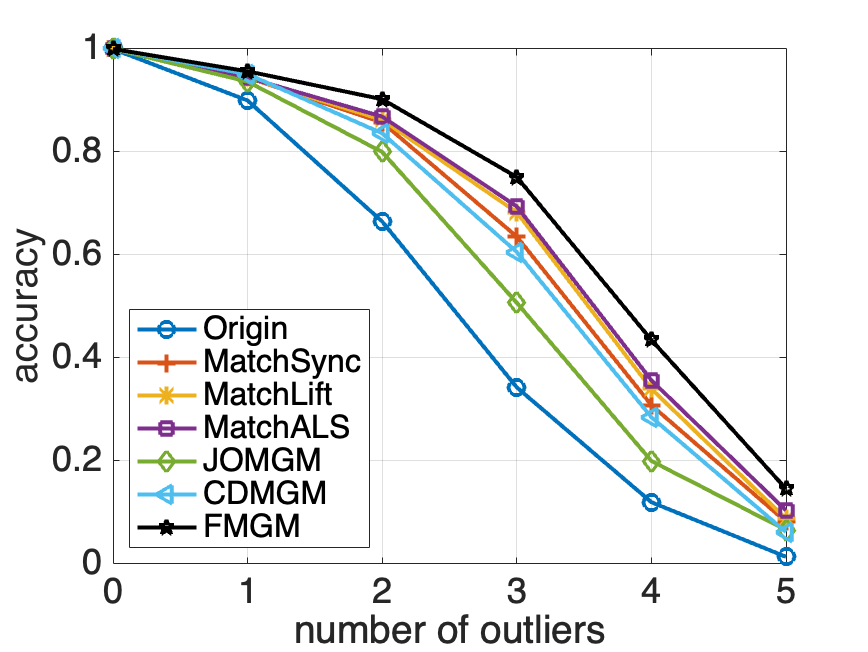

num = 6;
outlier = 0:num-1;
for i = [3, 6, 9, 12]
    fname = ['acc_outlier_',  num2str(i), '.mat'];
    acc = importdata(fname);
    figure, hold on;
    for k = 1:length(alglist)
        plot(outlier, acc(:, k), ['-', mklist(k)], 'DisplayName', alglist{k}, 'Color', cmap(k, :));
    end
    hold off;
    ylim([0, 1]);
    legend('Location', 'southwest');
    xlabel('number of outliers');
    ylabel('accuracy');
    exportgraphics(gcf, ['./imgs/', 'acc_', num2str(i), '_outlier.pdf']);
end